ES1

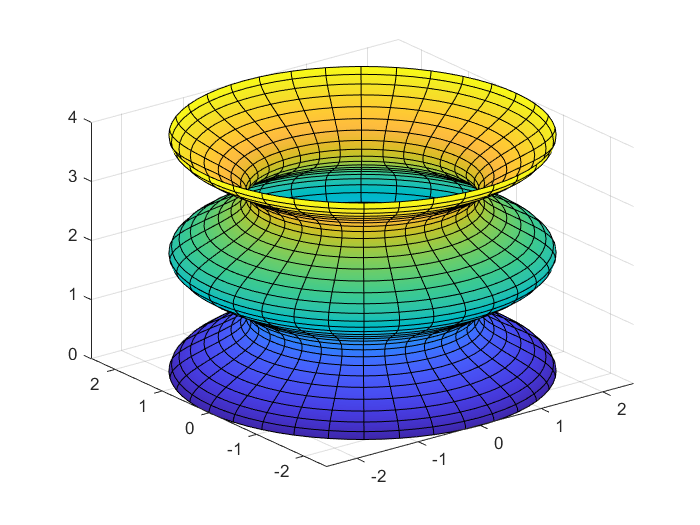

clear all
close all
syms z;
f= cos(pi*z)/2+2;
f1=diff(f);
f=matlabFunction(f);
f1=matlabFunction(f1);
zint=[0 4];tetaint=[0 2*pi];
x=@(z,teta) f(z).*cos(teta);
y=@(z,teta) f(z).*sin(teta);
z=@(z,teta) z;
fsurf(x,y,z,[zint tetaint])

surf=@(z) f(z).*sqrt(1+f1(z).^2);
areatot=2*pi*integral(surf,0,4)

areatot = 73.5734

vol=@(z) f(z).^2;
volume=pi*integral(vol,0,4)

volume = 51.8363

ES2

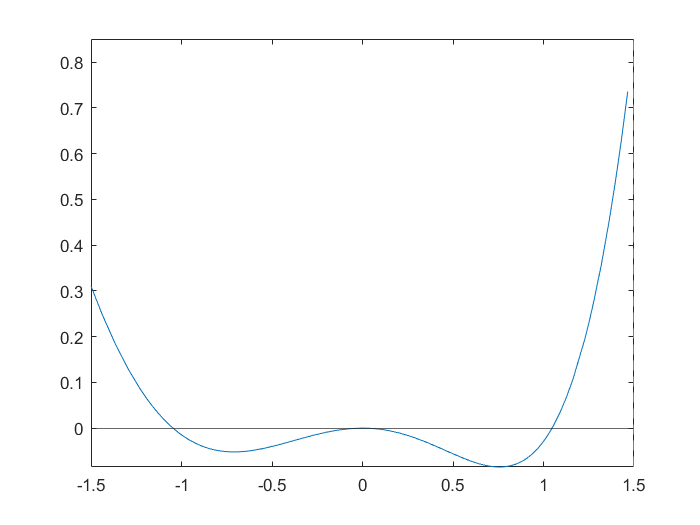

clear all
close all
syms x;
f=(exp(x)-1-x)*(1/2-cos(x));
f1=diff(f);
int=[-3/2 3/2];
fplot(f,int)
hold on
yline(0)
hold off

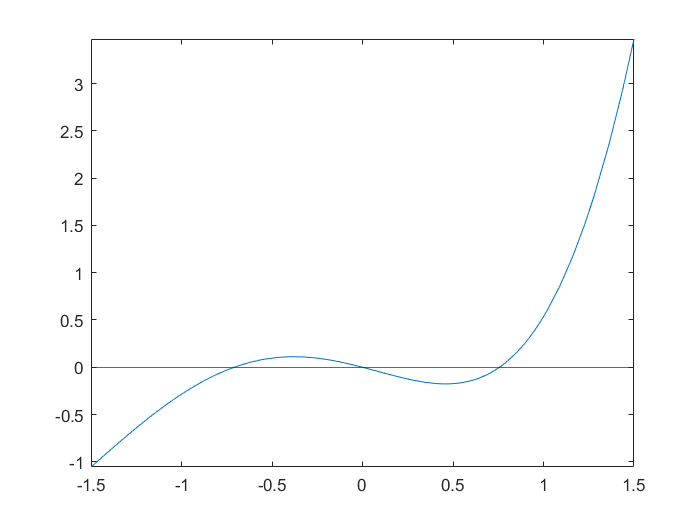

fplot(f1,int)
hold on
yline(0)
hold off

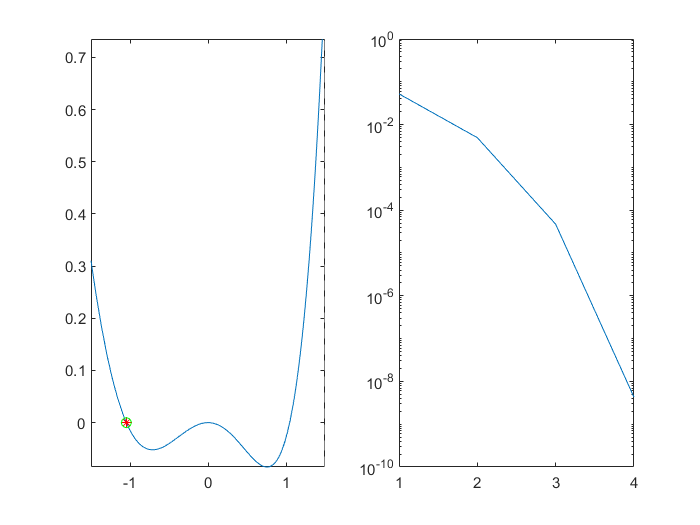

per x0=-1 si ha uno zero doppio
ordine di convergenza 1


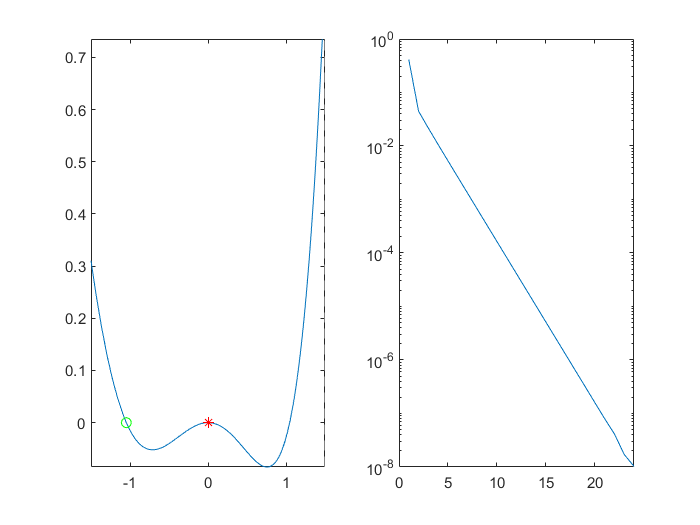

per x0=-0.5 si ha uno zero doppio
ordine di convergenza 1


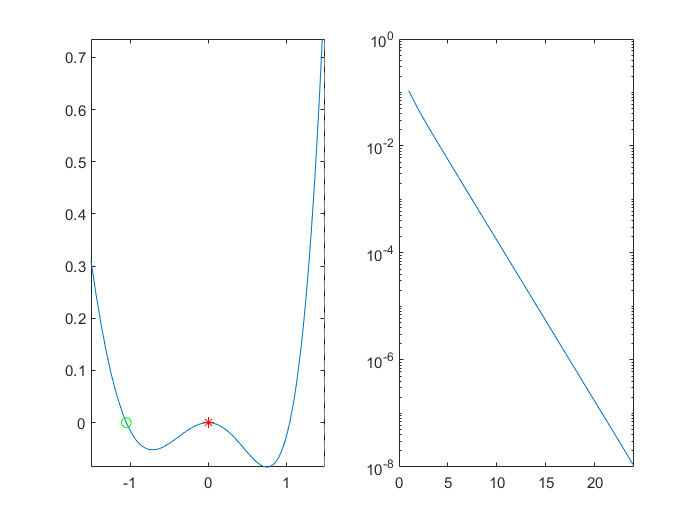

per x0=-0.2 si ha uno zero doppio
ordine di convergenza 1


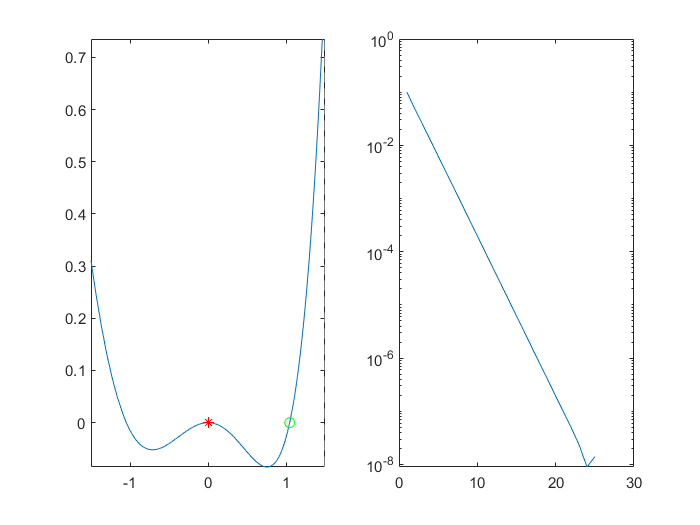

per x0=0.2 si ha uno zero doppio
ordine di convergenza 1


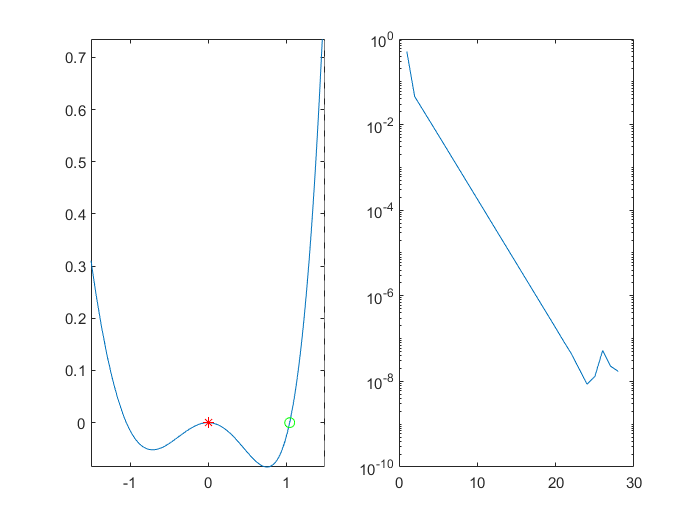

per x0=0.6 si ha uno zero doppio
ordine di convergenza 1


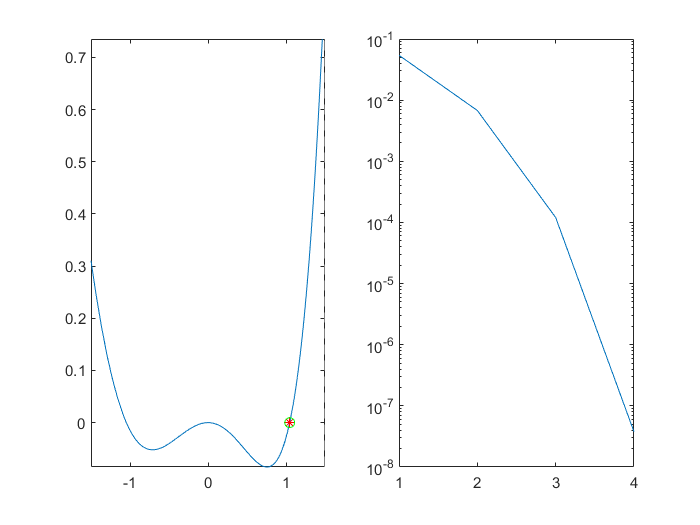

per x0=1 si ha uno zero singolo
ordine di convergenza 2


df=matlabFunction(f1);
toll=1e-9;Nmax=100;
for x0=[-1 -0.5 -0.2 0.2 0.6 1]
    figure
    subplot(1,2,1)
    fplot(f,int)
    hold on
    [zero,fz,iter,xk]=newton(f,x0,toll,Nmax);
    [zerof,fval,flag,out]=fzero(matlabFunction(f),x0);
    plot(zero,fz,"*r")
    plot(zerof,fval,"og")
    subplot(1,2,2)
    err=abs(xk(1:end-1)-xk(2:end));
    semilogy(err)
    ordineConv(df,x0,zero);
end

ES3

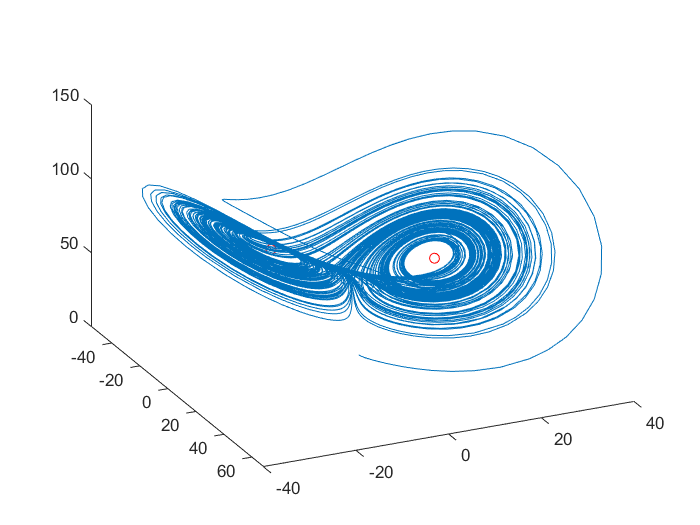

clear all
close all
int=[0 100];a=10;b=8/3;r=70;y0=[1;1;1];
y1=@(y) a*(y(2)-y(1));
y2=@(y) r*y(1)-y(2)-y(1).*y(3);
y3=@(y) -b*y(3)+y(1).*y(2);
Y=@(t,y) [y1(y);y2(y);y3(y)];
[t,u]=ode45(Y,int,y0);
plot3(u(:,1),u(:,2),u(:,3))
hold on
c=sqrt(b*r-b);
rcr=a*(a+b+3)/(a-b-1);
P1=[c;c;r-1];P2=[-c;-c;r-1];
plot3(P1(1),P1(2),P1(3),'or')
plot3(P2(1),P2(2),P2(3),'or')
view(25,-35)

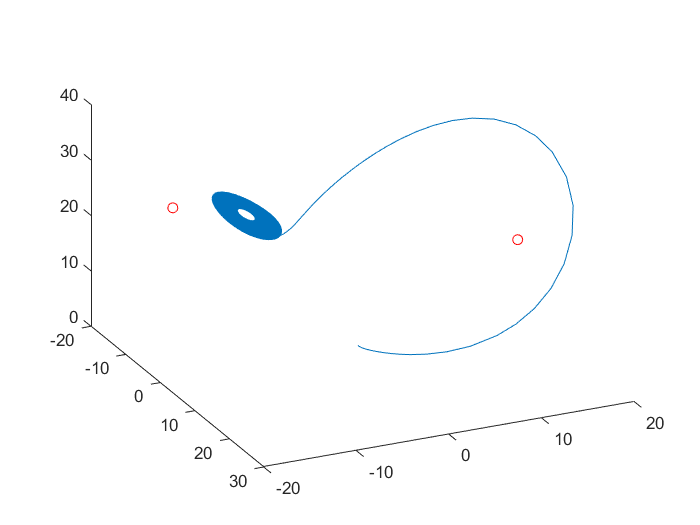

r=rcr-1;
y1=@(y) a*(y(2)-y(1));
y2=@(y) r*y(1)-y(2)-y(1).*y(3);
y3=@(y) -b*y(3)+y(1).*y(2);
Y=@(t,y) [y1(y);y2(y);y3(y)];
[t,u]=ode45(Y,int,y0);
figure
plot3(u(:,1),u(:,2),u(:,3))
hold on
P1=[c;c;r-1];P2=[-c;-c;r-1];
plot3(P1(1),P1(2),P1(3),'or')
plot3(P2(1),P2(2),P2(3),'or')
view(25,-35)

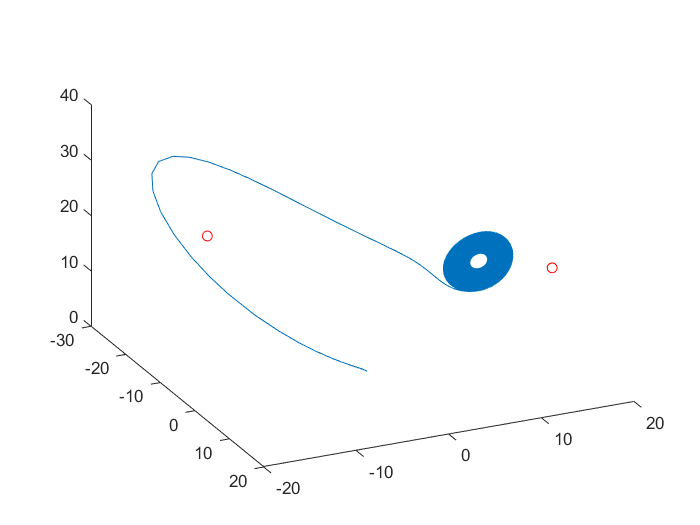

figure
y0=[-1;-1;1];
y1=@(y) a*(y(2)-y(1));
y2=@(y) r*y(1)-y(2)-y(1).*y(3);
y3=@(y) -b*y(3)+y(1).*y(2);
Y=@(t,y) [y1(y);y2(y);y3(y)];
[t,u]=ode45(Y,int,y0);
plot3(u(:,1),u(:,2),u(:,3))
hold on
P1=[c;c;r-1];P2=[-c;-c;r-1];
plot3(P1(1),P1(2),P1(3),'or')
plot3(P2(1),P2(2),P2(3),'or')
view(25,-35)